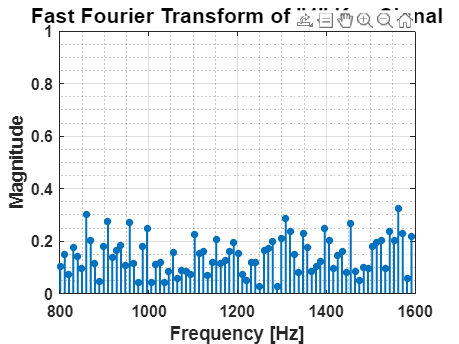

% Plot output_fft vs output_freq
% arm_rfft_fast_f32 calculates complex fft of the signal with a length of
% FFT_LENGTH
% odd elements of the array are real components - even elements are imag
% components.
% We need to find the magnitude of each complex number before plot.


fid = fopen('OutputFFT_for4.bin');
spectrum = fread(fid, inf, 'float');
fclose(fid);

fid = fopen('FrequencyFFT_for4.bin');
freq = fread(fid, inf, 'float');
fclose(fid);

% Process the spectrum data
real_spectrum = spectrum(1:2:end);
imag_spectrum = spectrum(2:2:end);
mag_spectrum = sqrt(real_spectrum.^2 + imag_spectrum.^2);

% Ensure vectors have same length
min_length = min(length(freq), length(mag_spectrum));
freq = freq(1:min_length);
mag_spectrum = mag_spectrum(1:min_length);

% Create the plot
figure;
stem(freq, mag_spectrum, 'filled', 'MarkerSize', 4, 'LineWidth', 1.5);

% Adjust axes to match the reference image
xlim([800 1600]);  % Set frequency range
ylim([0 1]);      % Set magnitude range

% Customize the appearance
set(gca, 'FontSize', 12, 'FontWeight', 'bold');
grid on;
xlabel('Frequency [Hz]', 'FontSize', 14, 'FontWeight', 'bold');
ylabel('Magnitude', 'FontSize', 14, 'FontWeight', 'bold');
title('Fast Fourier Transform of "4" Key Signal', 'FontSize', 16, 'FontWeight', 'bold');

% Add minor grid lines for better readability
set(gca, 'XMinorGrid', 'on', 'YMinorGrid', 'on');